## External Umbilical Hatch Aeroelasticity Calculations

Modelling hatch as flat plate restrained by torsional spring at leading edge. 

Divergence condition:

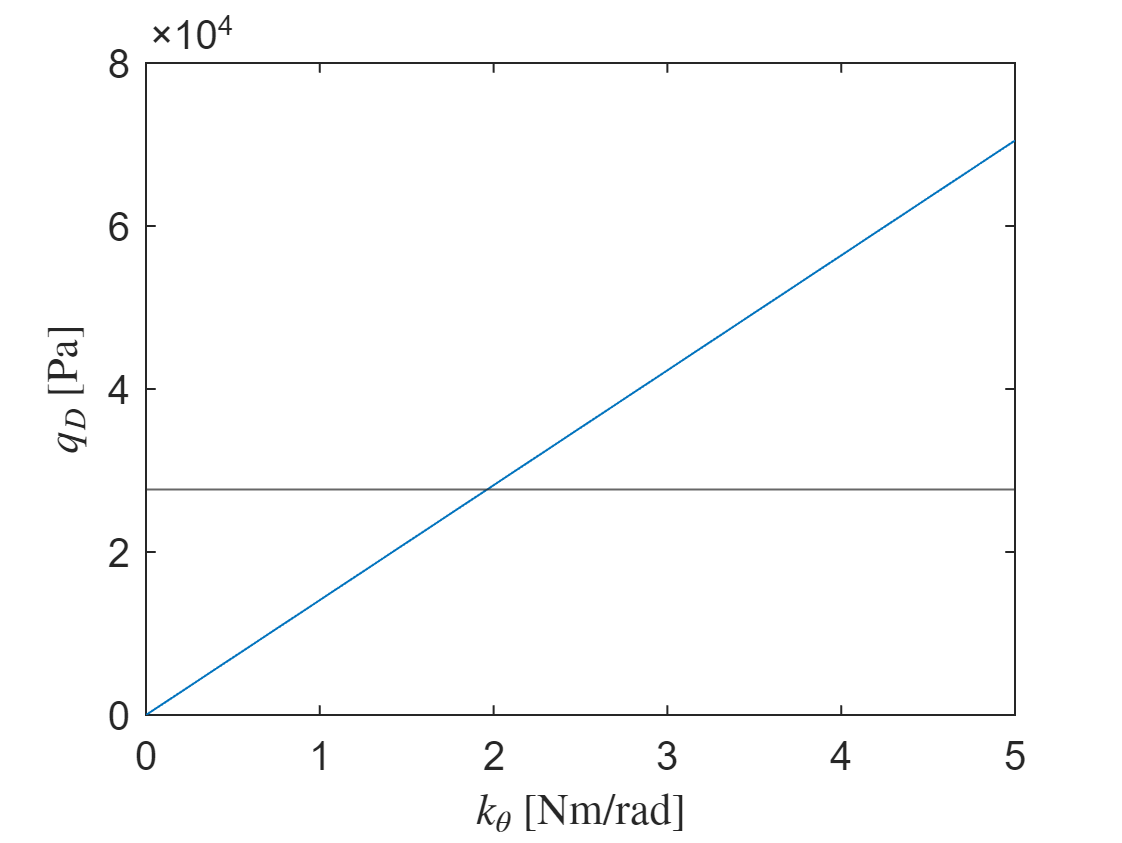

%   Housekeeping
clear
clc

%   Hatch parameters
length = 4.25; % Hatch length [cm]
width = 2.5; % Hatch width [cm]
q_inf_max = 24057; % Maximum dynamic pressure [Pa]

%   Safety factors
sf = 0.15; % []
q_inf_max = q_inf_max*(sf+1); % [Pa]

%   Unit conversions
length = length/100; % [m]
width = width/100; % [m]

%   Plotting divergence dynamic pressure for range of spring stiffness 
k_theta = linspace(0, 5, 100);
q_D = 2*k_theta/(length^2*width*pi);

plot(k_theta, q_D)
xlabel('$k_{\theta}$ [Nm/rad]','Interpreter','latex')
ylabel('$q_{D}$ [Pa]', 'Interpreter','latex')
yline(q_inf_max)


%   Finding minimum spring stiffness
k_theta_min = length^2*width*pi*q_inf_max/2;
disp(['Minimum spring stiffness: ', num2str(k_theta_min), ' Nm/rad'])

Minimum spring stiffness: 1.9624 Nm/rad
